# SVM Kernel Exploration

The purpose of this notebook is to try and determine the differences in the different SVM kernels that will be used in the kernel functions. The different kernel functions that will be explored for performance in kxcorr() function will be the RBF or gaussian_kernel, the cubic kernel, and the linear absolute value kernel. Those are defined as the following:

        RBF custom: 

                
$$K(x,y) = exp(\frac{-1}{\sigma^2 \alpha (x \odot y)})$$


        Cubic kernel:

                
$$K(x,y) = -(x \odot y + 1)^3$$


        Linear-absolute value kernel:

                
$$K(x,y) = |(x - y)|$$


Indicating that $x \odot y$ is the equivalent of the element wise matrix multiplication of the signal vectors. They must be the same length, so the ref signal must be zero-padded. 

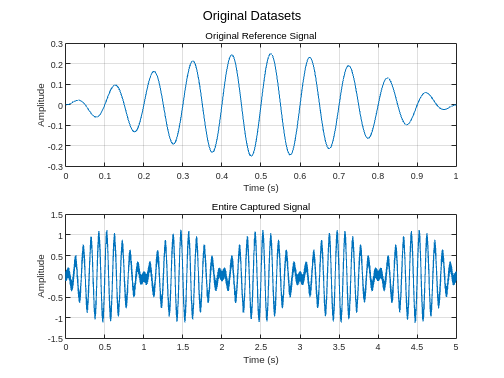

% --Setup
    clear; clc; format compact; close all;

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

    % --Plot
        figure()
        subplot(2,1,1)
        plot(t,ref_signal)
            hold on
            grid on
            subtitle('Original Reference Signal')
            ylabel("Amplitude")
            xlabel("Time (s)")

% --Creating sample signal
    t1 = 0:1/fs:5;
    amplitude = 1;
    envelope = amplitude.* sin(pi*t1);
    signal = envelope .* sin(f*t1);
    noisy_signal = randi(100,1,length(t1))./400 + signal;
    noisy_signal = noisy_signal - mean(noisy_signal);

% --Plotting
    subplot(2,1,2)
    plot(t1 , noisy_signal)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Amplitude")
        subtitle("Entire Captured Signal")
        sgtitle("Original Datasets")

## Exploring Linear Abs Value Kernel

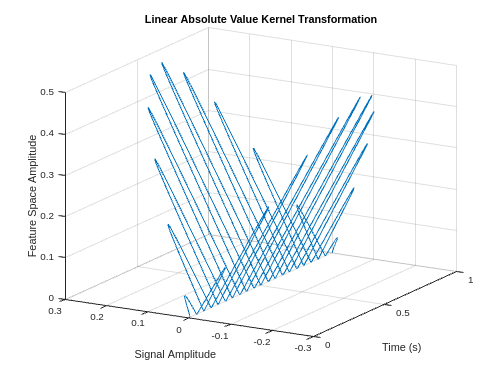

% --Find L-Abs Kernel of the function
    f_sig = fft(ref_signal);
    kf = Labs_kernel(f_sig,f_sig);

% --Plot kernel
    figure()
    plot3(t, ref_signal, kf)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Feature Space Amplitude")
        title("Linear Absolute Value Kernel Transformation")
        view([-60 20])

This could be good for white noise where we have a cyclic signal where we are trying to distinguish the cyclic signal vs. random noise. Lets look at what the random noise would look like under the kernel transformation. 

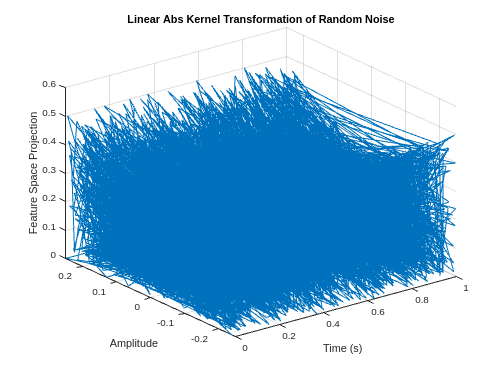

% --Creating random noise
    random_noise = randi([-25 25], 1, 10001)/100;
    f_rando = fft(random_noise);

% --Finding the kernel
    kf = Labs_kernel(f_rando, f_rando);

% --Plot
    figure()
    plot3(t, random_noise, kf)
        xlabel("Time (s)")
        ylabel("Amplitude")
        zlabel("Feature Space Projection")
        hold on
        grid on
        title("Linear Abs Kernel Transformation of Random Noise")

The kernel transformation of random noise of the same amplitude has half the amplitude of the linear absolute value kernel. This bodes well for the signal detection, because our deterministic signals are going to be raised above the noise creating the ability to linearly separate and detect the signals. The raised feature space could allow the correlation algorithm to pick out signals better. This could be good for white noise detection algorithms. This may not be so good for colored noise algorithms. 

## Exploring The Cubic Kernel

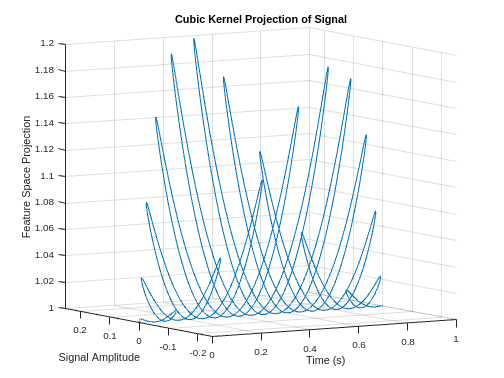

% --Cubic kernel
    kf = cubic_kernel(f_sig, f_sig);

% --Plot
    figure()
    plot3(t, ref_signal, kf)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Feature Space Projection")
        title("Cubic Kernel Projection of Signal")   
        view([-31 7])

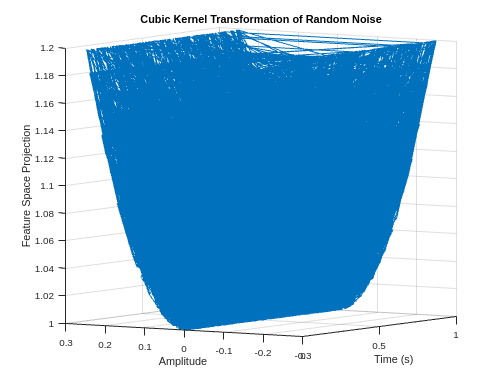

% --Using cubic kernel on random noise
    kf = cubic_kernel(f_rando, f_rando);

% --Plot random noise
    figure()
    plot3(t, random_noise, kf)
        xlabel("Time (s)")
        ylabel("Amplitude")
        zlabel("Feature Space Projection")
        hold on
        grid on
        title("Cubic Kernel Transformation of Random Noise")
        view([-57 5])

This also has a similar trend vs. the random noise that will allow for signals to be raised below the noise in the feature space where we can see the deterministic part of the signal away from the random nose where the signal will be centered at 0 and the noise will be centered at the amplitude of the kernel transformation of signal at t = 0. 

## Exploring the RBF Function

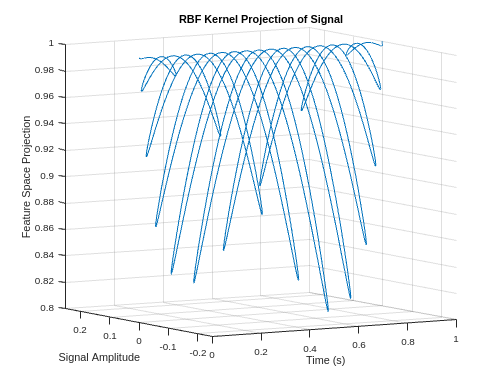

% --Finding kernel of data
    kf = gaussian_kernel(f_sig, f_sig, 0.3);

% --Plot
    figure()
    plot3(t, ref_signal, kf)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Feature Space Projection")
        title("RBF Kernel Projection of Signal")   
        view([-31 7])

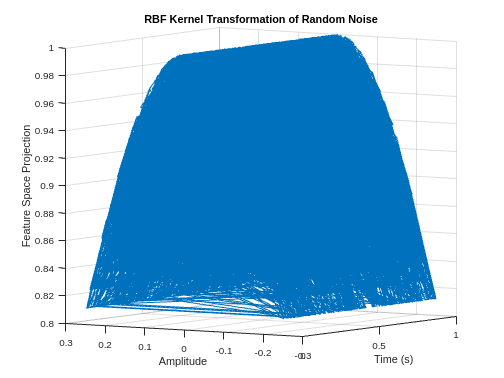

% --Using RBF kernel on random noise
    kf = gaussian_kernel(f_rando, f_rando, 0.3);

% --Plot random noise
    figure()
    plot3(t, random_noise, kf)
        xlabel("Time (s)")
        ylabel("Amplitude")
        zlabel("Feature Space Projection")
        hold on
        grid on
        title("RBF Kernel Transformation of Random Noise")
        view([-57 5])

Because of the relative amplitudes of the noise, we cannot say that there is a benefit in terms of the RBF kernel when defining the hyperplane for the detection of signals because the data still falls in line with the deterministic signal. This could indicate poor performance for white noise but could be more beneficial for colored noise as most of the colored noise is deterministic in nature. The amplitude of the noise transformation lies directly in the middle of the signal transformation. 

Because of the properties of the RBF with scale-space filtering, we could use this for colored noise and therefore could see a higher performance with the deterministic colored noise in signal detection vs. the other kernel functions. 

## Creating Basic Signal With White Noise

% --zero-padding signal
    long_signal = [zeros(1, 10000), ref_signal, zeros(1, 10000)];
    random_noise_long = randi([-250 250], 1, length(long_signal))/1000;
    long_noisy_signal = long_signal + random_noise_long;
    time_long = 0:1/fs:(length(long_signal) - 1) / fs;

% --Statistical properties of the white noise
    Expected_val = mean(random_noise_long)

Expected_val = 5.3128e-04

    standard_dev = std(random_noise_long)

standard_dev = 0.1444

% --Calculating SNR values
    noise_power = sum(random_noise.^2)/(2*length(random_noise) + 1);
    signal_power = sum(long_signal.^2)/(2*length(long_signal) + 1);
    SNR = 10*log10(signal_power/noise_power)

SNR = -6.2159

## Finding Kernel Transformations of the Signal

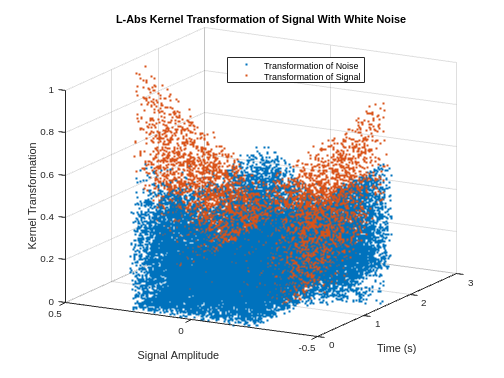

% --Taking fft_s
    f_long_signal = fft(long_noisy_signal);
    f_noise = fft(random_noise_long);

% --Finding Kernel Transformations
    kf = Labs_kernel(f_long_signal,f_long_signal);

% --Pull out parts of the signal
    kf_signal = kf(:,10002:20002);
    time_new = 1:1/fs:2;
    kf_noise = Labs_kernel(f_noise, f_noise);

% --Plotting
    figure()
    plot3(time_long, long_noisy_signal, kf_noise, '.')
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        title("L-Abs Kernel Transformation of Signal With White Noise")
        
    plot3(time_new, long_noisy_signal(:,10002:20002), kf_signal, '.')
        legend("Transformation of Noise","Transformation of Signal")
        view([-61.200 18.667])
        legend("Position", [0.4524,0.78042,0.27128,0.067857])

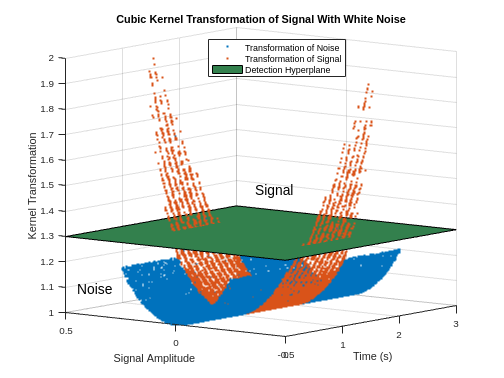

% --Cubic Kernel Transformation
    kf = cubic_kernel(f_long_signal, f_long_signal);

% --Pull out parts of the signal
    kf_signal = kf(:,10002:20002);
    time_new = 1:1/fs:2;
    kf_noise = cubic_kernel(f_noise, f_noise);

% --Plotting
    figure()
    plot3(time_long, long_noisy_signal, kf, '.')
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        title("Cubic Kernel Transformation of Signal With White Noise")
        
    plot3(time_new, long_noisy_signal(:,10002:20002), kf_signal, '.')
        view([-52.200 8.667])
        legend("Position", [0.4147,0.81217,0.27128,0.067857])

% --Creating the hyperplane
    x = [0 3];
    y = [-0.5 0.5];
    z = [1.3 1.3
         1.3 1.3];
    surf(x, y, z, 'FaceColor',[0.2 0.5 0.3])
        legend("Transformation of Noise", "Transformation of Signal", "Detection Hyperplane")
        text(1, -0.1, 1.5, "Signal",'FontSize',14)
        text(0, 0.45, 1.1, "Noise","FontSize",14)

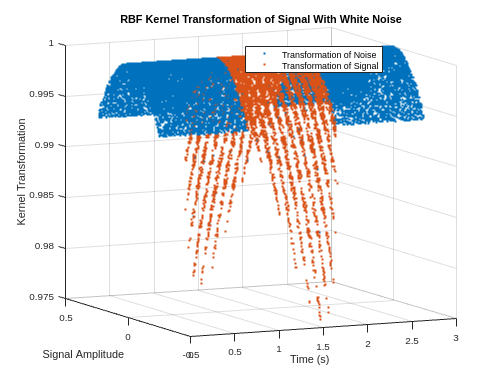

% --RBF Kernel Transformation
    kf = gaussian_kernel(f_long_signal, f_long_signal, 10);

% --Pull out parts of the signal
    kf_signal = kf(:,10002:20002);
    time_new = 1:1/fs:2;

% --Plotting
    figure()
    plot3(time_long, long_noisy_signal, kf, '.')
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        title("RBF Kernel Transformation of Signal With White Noise")
        
    plot3(time_new, long_noisy_signal(:,10002:20002), kf_signal, '.')
        legend("Transformation of Noise","Transformation of Signal")
        view([-25.200 9.334])
        legend("Position", [0.48812,0.80952,0.27128,0.067857])

## Function Definitions:

####         Kxcorr() function definition:

function output = kxcorr(data, sample)

        % --Test for column vector
            vec1 = iscolumn(data);
            vec2 = iscolumn(sample);

            if vec1 == 1
                data = data';
            elseif vec2 == 1
                sample = sample';
            end

        % --zero pad sample data to make same length
            if length(sample) < length(data)
                diff = length(data) - length(sample);
                pad = zeros([1, diff]);
                sample = [sample, pad];
            end

        % --Parameters
            lambda = 0.001;
            sigma = 0.2;

        % --Setup
            data_fft = fft(data);

        % --Train Model
            correlator = train(data, sample, lambda, sigma);

        % --Compute output
            kernel_fft = fft(gaussian_kernel(data_fft, correlator.sample_fft, sigma));
            output = abs(ifft(correlator.h_hat .* kernel_fft));
            output = output - mean(output);

end

####         Gaussian Kernel Definition:

    function kf = gaussian_kernel(xf, yf, sigma)
    
        % --Setup Parameters
	        N = numel(xf);

        % --Perform Auto and Cross correlations
	        xx = xf(:)' * xf(:) / N;
	        yy = yf(:)' * yf(:) / N;
	        xy = ifft(xf .* conj(yf));
            x = ifft(xf);
            y = ifft(yf);
	    
        % --Find Kernel
            kf = exp(-(x.^2 + y.^2) ./ (2*sigma));

    end

####         L-abs Kernel Definition:

    function kf = Labs_kernel(xf, yf)
        
        % --Setup
            xy = ifft(xf - conj(yf));

        % --Find the kernel
            kf = abs(xy);

    end

####         Cubic Kernel Definition:

    function kf = cubic_kernel(xf, yf)

        % --Setup parameters
            x = ifft(xf);
            y = ifft(yf);
            xy = ifft(xf .* conj(yf));

        % --Find Kernel
            kf = (x.*y + 1).^3;


    end

####         Training Definition:

% --Define train() [COMBO TRAIN THAT IS USED BY BOTH]
    function correlator = train(data, sample, lambda, sigma)

        % --Early properties of the correlator
            correlator.sigma = sigma; 
            sample_fft = fft(sample);
            correlator.sample_fft = sample_fft;

        % --Calculating correlator 
            kernel = gaussian_kernel(sample_fft, sample_fft, sigma);
            kernel = kernel - mean(kernel);
            k_z = fft(kernel);

        % --Define training objective set (Uncomment sections)

            % --Triangular wave trainer
                x = 0:length(sample)/2;
                x = [x flip(x)];
                x = x(1:end - 1);
                g_hat = 1/max(x) .* x;
                g_hat_1 = abs(fft(g_hat));

            % --Correlation trainer 
                g_hat = xcorr(data, sample);
                g_hat = g_hat(1, round(length(g_hat)/2):end)./length(g_hat);
                g_hat_2 = abs(fft(g_hat));
                g_hat = g_hat_1 .* g_hat_2;          
            
        % --Define h_hat for our system
            % uses the following equation: h_hat = g_hat ./ k(sample)
            correlator.h_hat = g_hat./(k_z + lambda);
    end